## Linear parametrization

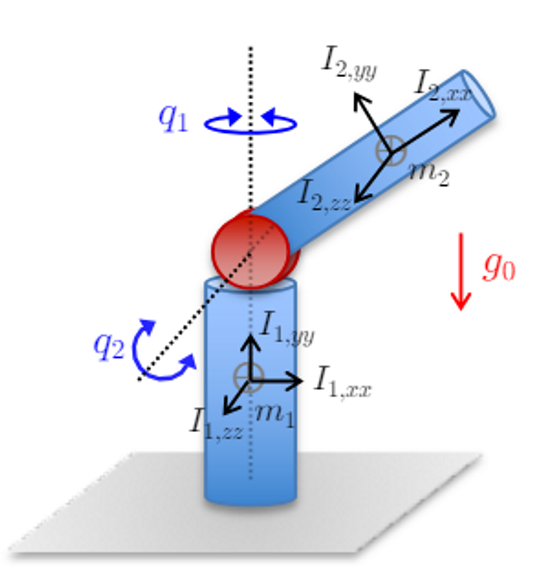

syms q1 q2 q3 l1 l2 l3 m1 m2 m3 d1 d2 d3 I1 I2xx I2yy I2zz I3 g0 real
syms dq1 dq2 dq3 ddq1 ddq2 real

%% Kinetic energy of joint 1
y1 = 0;
x1 = d1;
z1 = q1;

vx1 = diff(x1, q1)*dq1 + diff(x1, q2)*dq2 + diff(x1, q3)*dq3;
vy1 = diff(y1, q1)*dq1 + diff(y1, q2)*dq2 + diff(y1, q3)*dq3;
vz1 = diff(z1, q1)*dq1 + diff(z1, q2)*dq2 + diff(z1, q3)*dq3;

T1 = 0.5*m1*[vx1 vy1 0]*[vx1; vy1; 0;] + 0.5*I1*[0 0 vz1]*[0; 0; vz1;];

disp('velocity of joint 1: ');

velocity of joint 1: 


disp([vx1; vy1; vz1;]);

$$\left(\begin{array}{c} 0\\ 0\\ {\mathrm{dq}}_{1} \end{array}\right)$$


disp('Kinetic Energy of joint 1: ');

Kinetic Energy of joint 1: 


disp(T1);

$$\frac{I_{1}\,{{\mathrm{dq}}_{1}}^{2}}{2}$$


%% Kinetic energy of joint 2
y2 = d2*sin(q1)*cos(q2);
x2 = d2*cos(q2)*cos(q1);
z2 = d2*sin(q2);

vx2 = diff(x2, q1)*dq1 + diff(x2, q2)*dq2 + diff(x2, q3)*dq3;
vy2 = diff(y2, q1)*dq1 + diff(y2, q2)*dq2 + diff(y2, q3)*dq3;
vz2 = diff(z2, q1)*dq1 + diff(z2, q2)*dq2 + diff(z2, q3)*dq3;

T2 = 0.5*m2*(d2^2)*(dq2^2 + (cos(q2)^2)*(dq1^2)) + 0.5*I2zz*dq2^2 + 0.5*(I2xx*sin(q2)^2 + I2yy*cos(q2)^2)*dq1^2;

disp('velocity of joint 2: ');

velocity of joint 2: 


disp([vx2; vy2; vz2;]);

$$\left(\begin{array}{c} -d_{2}\,{\mathrm{dq}}_{1}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)-d_{2}\,{\mathrm{dq}}_{2}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ d_{2}\,{\mathrm{dq}}_{1}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)-d_{2}\,{\mathrm{dq}}_{2}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ d_{2}\,{\mathrm{dq}}_{2}\,\cos\left(q_{2}\right) \end{array}\right)$$


disp('Kinetic Energy of joint 2: ');

Kinetic Energy of joint 2: 


disp(T2);

$${{\mathrm{dq}}_{1}}^{2}\,\left(\frac{\mathrm{I2yy}\,{\cos\left(q_{2}\right)}^{2}}{2}+\frac{\mathrm{I2xx}\,{\sin\left(q_{2}\right)}^{2}}{2}\right)+\frac{\mathrm{I2zz}\,{{\mathrm{dq}}_{2}}^{2}}{2}+\frac{{d_{2}}^{2}\,m_{2}\,\left({{\mathrm{dq}}_{1}}^{2}\,{\cos\left(q_{2}\right)}^{2}+{{\mathrm{dq}}_{2}}^{2}\right)}{2}$$


T = simplify(T1 + T2, 'Steps', 1000);
disp('Total Kinetic Energy: ');

Total Kinetic Energy: 


disp(T);

$$\frac{I_{1}\,{{\mathrm{dq}}_{1}}^{2}}{2}+\frac{\mathrm{I2zz}\,{{\mathrm{dq}}_{2}}^{2}}{2}-{{\mathrm{dq}}_{1}}^{2}\,\left(\frac{\mathrm{I2xx}\,\left({\cos\left(q_{2}\right)}^{2}-1\right)}{2}-\frac{\mathrm{I2yy}\,{\cos\left(q_{2}\right)}^{2}}{2}\right)+\frac{{d_{2}}^{2}\,m_{2}\,\left({{\mathrm{dq}}_{1}}^{2}\,{\cos\left(q_{2}\right)}^{2}+{{\mathrm{dq}}_{2}}^{2}\right)}{2}$$


%% Inertia Matrix
M11 = diff(diff(T, dq1), dq1);
M12 = diff(diff(T, dq1), dq2);
M21 = diff(diff(T, dq2), dq1);
M22 = diff(diff(T, dq2), dq2);

M = [M11, M12;
     M21, M22;];

M = simplify(M, 'Steps', 1000);

disp('The inertia matrix M(q) is:');

The inertia matrix M(q) is:


disp(M);

$$\left(\begin{array}{cc} I_{1}-\mathrm{I2xx}\,\left({\cos\left(q_{2}\right)}^{2}-1\right)+\mathrm{I2yy}\,{\cos\left(q_{2}\right)}^{2}+{d_{2}}^{2}\,m_{2}\,{\cos\left(q_{2}\right)}^{2} & 0\\ 0 & m_{2}\,{d_{2}}^{2}+\mathrm{I2zz} \end{array}\right)$$


%% Coriolis and Centrifugal forces
q  = [q1; q2];
dq = [dq1; dq2];

[C, c_sub] = compute_christoffel_matrix(M, q, dq, 1000);

disp('La matrice di Coriolis C(q,dq) è:');

La matrice di Coriolis C(q,dq) è:


disp(c_sub);

    {2×2 sym}    {2×2 sym}




disp('Il vettore c(q,dq) = C(q,dq)*dq è:');

Il vettore c(q,dq) = C(q,dq)*dq è:


disp(C);

$$\left(\begin{array}{c} \left(-\sin\left(2\,q_{2}\right)\,\left(m_{2}\,{d_{2}}^{2}-\mathrm{I2xx}+\mathrm{I2yy}\right)\right)\,{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{2}\\ \frac{\sin\left(2\,q_{2}\right)\,\left(m_{2}\,{d_{2}}^{2}-\mathrm{I2xx}+\mathrm{I2yy}\right)}{2}\,{{\mathrm{dq}}_{1}}^{2} \end{array}\right)$$


%% Gravity terms
U1 = 0;
U2 = m2*g0*d2*sin(q2);

U = [U1 + U2];
g_q = simplify([diff(U, q1); diff(U, q2)], 'Steps', 100);

disp('Potential Energy: ');

Potential Energy: 


disp(U);

$$d_{2}\,g_{0}\,m_{2}\,\sin\left(q_{2}\right)$$

disp('Gravity terms g(q): ');

Gravity terms g(q): 


disp(g_q);

$$\left(\begin{array}{c} 0\\ d_{2}\,g_{0}\,m_{2}\,\cos\left(q_{2}\right) \end{array}\right)$$


%% Linearization
tau = M * [ddq1; ddq2] + g_q;

disp('tau: ');

tau: 


disp(tau);

$$\left(\begin{array}{c} {\mathrm{ddq}}_{1}\,\left(I_{1}-\mathrm{I2xx}\,\left({\cos\left(q_{2}\right)}^{2}-1\right)+\mathrm{I2yy}\,{\cos\left(q_{2}\right)}^{2}+{d_{2}}^{2}\,m_{2}\,{\cos\left(q_{2}\right)}^{2}\right)\\ {\mathrm{ddq}}_{2}\,\left(m_{2}\,{d_{2}}^{2}+\mathrm{I2zz}\right)+d_{2}\,g_{0}\,m_{2}\,\cos\left(q_{2}\right) \end{array}\right)$$

function [C, c_sub] = compute_christoffel_matrix(inertia_matrix, joint_pos, joint_vel, opt_steps)
    
    % inertia_matrix: expression of inertia matrix
    % joint_pos: variable of joint position q_i
    % ch_matrix_disp: can be true or false, it is used to display the
    % single christoffel matrix

    c_sub = {};

    M = inertia_matrix;
    n_joint = length(joint_pos);
    C = sym(zeros(n_joint, 1));
    joint_pos = reshape(joint_pos, n_joint, 1);
    joint_vel = reshape(joint_vel, n_joint, 1);

    for k = 1:n_joint
        joint = joint_pos(k);
        mk = M(:,k); % inertia matrix of joint k, its a columns
    
        %term1 = jacobian(mk,joint_pos);
        %term2 = jacobian(mk,joint_pos);
        %term3 = diff(M,joint);
        %ck = (1/2)*(term1 + transpose(term2) - term3 );

        ck = (1/2)*(jacobian(mk,joint_pos)+transpose(jacobian(mk,joint_pos))-diff(M,joint));
        ck = simplify(ck, Steps=opt_steps);
        c_sub{k} = ck;

        C(k) = simplify(transpose(joint_vel)*ck*joint_vel);
    end
    
    C = simplify(C, Steps=opt_steps);
    C = collect(C, joint_vel);
end